## Number of Turns in Rx

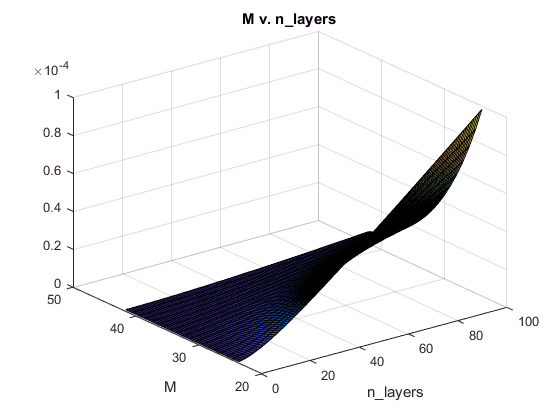

TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
TX_NL = 3;
RX_NL = 1;
R_sense = 100;

TARGET_F = 20e3; % Hz
RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;


x = 1:100;
awg = 24:42;
tx = Coil.FromWindings(TX_D, TX_NT, TX_NL, TX_AWG, TARGET_F, 0);
Bfield = Field(RX_LOC, tx);
y_all = [];
for n_turns = x
    y = [];
    for rx_awg = awg
        rx = Coil.FromWindings(RX_D, n_turns, RX_NL, rx_awg, TARGET_F, 0);
        [M, TX_I, measurement, RX_V] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
        y = [y;max(abs(RX_V))];
    end
    y_all = [y_all, y];
end

figure();
%plot(x, y); xlabel('n\_layers'); ylabel('M'); title('M v. n\_layers');
surf(x, awg, y_all); xlabel('n\_layers'); ylabel('M'); title('M v. n\_layers');

clear all;
TX_D = 90e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

TARGET_F = 20e3; % Hz
RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;


x = [1:1:40]*1e-3;
y = [];
tx = Coil.FromWindings(TX_D, TX_NT, NL, TX_AWG, TARGET_F, 100);
Bfield = Field(RX_LOC, tx);
disp(Bfield.B(3));
for rx_d = x
    rx = Coil.FromWindings(rx_d, RX_NT, NL, RX_AWG, TARGET_F, 0);
    [M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
    y = [y;min(measurement), max(measurement)];
end

figure();
plot(x*1000, y); xlabel('rx diameter'); ylabel('measurement'); title('rx diameter');

## Tx Size

clear all;
TX_D = 90e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

NL = 5

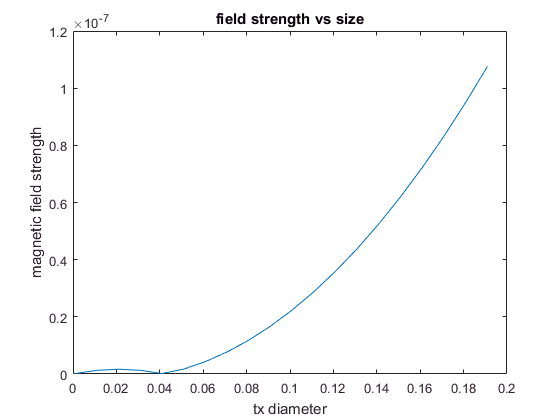


TARGET_F = 20e3; % Hz
RX_LOC = [1000,0,0] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;
RX_D = 10;

x = [1:10:200]*1e-3;
y = [];
for tx_d = x
    tx = Coil.FromWindings(tx_d, TX_NT, NL, TX_AWG, TARGET_F, 100);
    
    Bfield = Field(RX_LOC, tx);
    y = [y; sqrt(sum(Bfield.B.^2))];
    %rx = Coil.FromWindings(RX_d, RX_NT, NL, RX_AWG, TARGET_F, 0);
    %[M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
    %y = [y;min(measurement), max(measurement)];
end

figure();
plot(x, y); xlabel('tx diameter'); ylabel('magnetic field strength'); title('field strength vs size');

TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

NL = 5

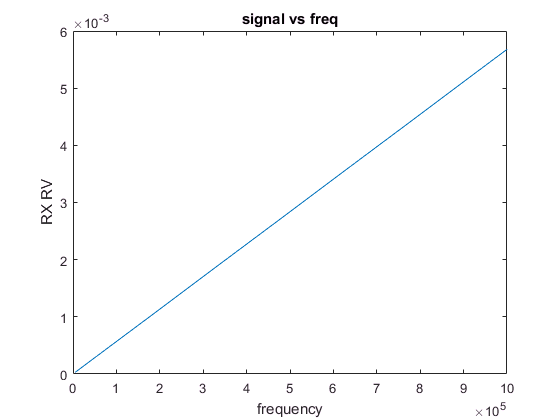


RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TX_V = 10;


x = [5:5:1000]*1e3;
y_all = [];
y2 = [];

for f = x
    for c_offset = -10e-9:1e-9:10e-9
        tx = Coil.FromWindings(TX_D, TX_NT, NL, TX_AWG, f, 0);
        tx.C = tx.C + c_offset
        rx = Coil.FromWindings(RX_D, RX_NT, NL, RX_AWG, f, 0);
        Bfield = Field(RX_LOC, tx);
        [M, TX_I, measurement, RX_V] = GetMeasurements(Bfield, rx, tx, f, TX_V);
        y = [y;max(abs(RX_V))];
        y2 = [y2;max(abs(TX_I))];
    end
end

figure();
plot(x, y); xlabel('frequency'); ylabel('RX RV'); title('signal vs freq');

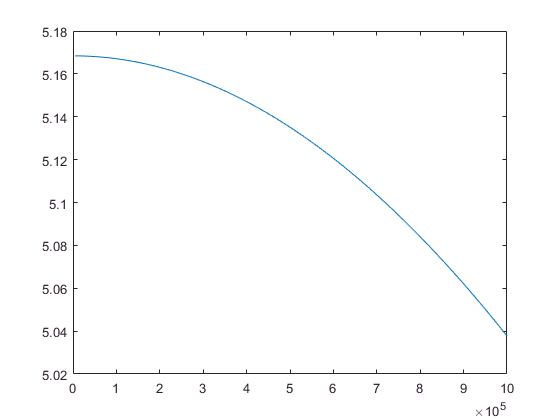

figure();
plot(x, y2); 

clear all;
TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_NT = 10;    % # turns/layer
RX_NT = 10;
NL = 5

RX_LOC = [0,0,32] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TARGET_F = 20e3; % Hz
TX_V = 10;


x = [20:2:42];
y = [];
for awg = x
    tx = Coil.FromWindings(TX_D, TX_NT, NL, awg, TARGET_F, 0);
    rx = Coil.FromWindings(RX_D, RX_NT, NL, awg, TARGET_F, 0);
    Bfield = Field(RX_LOC, tx);
    [M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
    y = [y;min(measurement), max(measurement)];
end

figure();
plot(x, y); xlabel('n\_layers'); ylabel('M'); title('M v. n\_layers');

clear all;
TX_D = 90e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 20;    % # turns/layer
RX_NT = 10;
NL = 5

RX_LOC = [0,0,0] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TARGET_F = 200e3; % Hz
TX_V = 10;


tx = Coil.FromWindings(TX_D, TX_NT, NL, TX_AWG, TARGET_F, 100);
rx = Coil.FromWindings(RX_D, RX_NT, NL, RX_AWG, TARGET_F, 0);
Bfield = Field(RX_LOC, tx);
[M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
figure; plot(measurement);

clear all;
TX_D = 100e-3;   % coil diameter [m]
RX_D = 20e-3;   % coil diameter [m]
TX_AWG = 26;   % wire gauge [AWG]
RX_AWG = 26;
TX_NT = 10;    % # turns/layer
RX_NT = 10;
RX_NL = 3;
TX_NL = 5;

RX_LOC = [0,0,0] .* 1e-3;     % receiver coil location (x,y,z) [m]


mu_rel = 1;
mu = 4*pi*1e-7 * mu_rel;

TARGET_F = 140e3; % Hz
TX_V = 10;


rx = Coil.FromL(RX_D, RX_NT, RX_NL, RX_AWG, TARGET_F, .11e-3, 0);
tx = Coil.FromL(TX_D, TX_NT, TX_NL, TX_AWG, TARGET_F, .11e-3, 1);
Bfield = Field(RX_LOC, tx);
[M, TX_I, measurement] = GetMeasurements(Bfield, rx, tx, TARGET_F, TX_V);
figure; plot(measurement);